# Make Simulink Application hardware-aware using NXP's MBDT for S32K3

After the Motor Control Current Fault Detection system was tested against different use-cases through the **MiL**, **SiL** and** PiL** validation and verification techniques, it`s time to connect the inputs and outputs to the real signals and automatically generate code from Simulink, build & deploy our model on the S32K396. 

In this scope, we will use some of the **NXP`s Model-Based Design Toolbox** blocks, and by adding them into our Simulink canvas we will make the model hardware-aware. As an evaluation hardware kit to test our algorithm, we will use the [**S32K396-BGA-DC1**](https://www.nxp.com/design/design-center/development-boards-and-designs/automotive-development-platforms/s32k-mcu-platforms/s32k39-37-36-electrification-microcontrollers-evaluation-board:S32K396-BGA-DC1), optimized for developing electrification applications.

### The main topics to cover for the next exercises are:

- Add **MBDT** blocks from MBDT Simulink Library Browser into our model;

- Configure **MCU Pins, Clocks & Peripherals** using** S32 Configuration Tools**;

- Generate Code, Build & Deploy the Simulink model on the **S32K396-BGA-DC1**;

- Verify application functionality, using **FreeMASTER **tool;

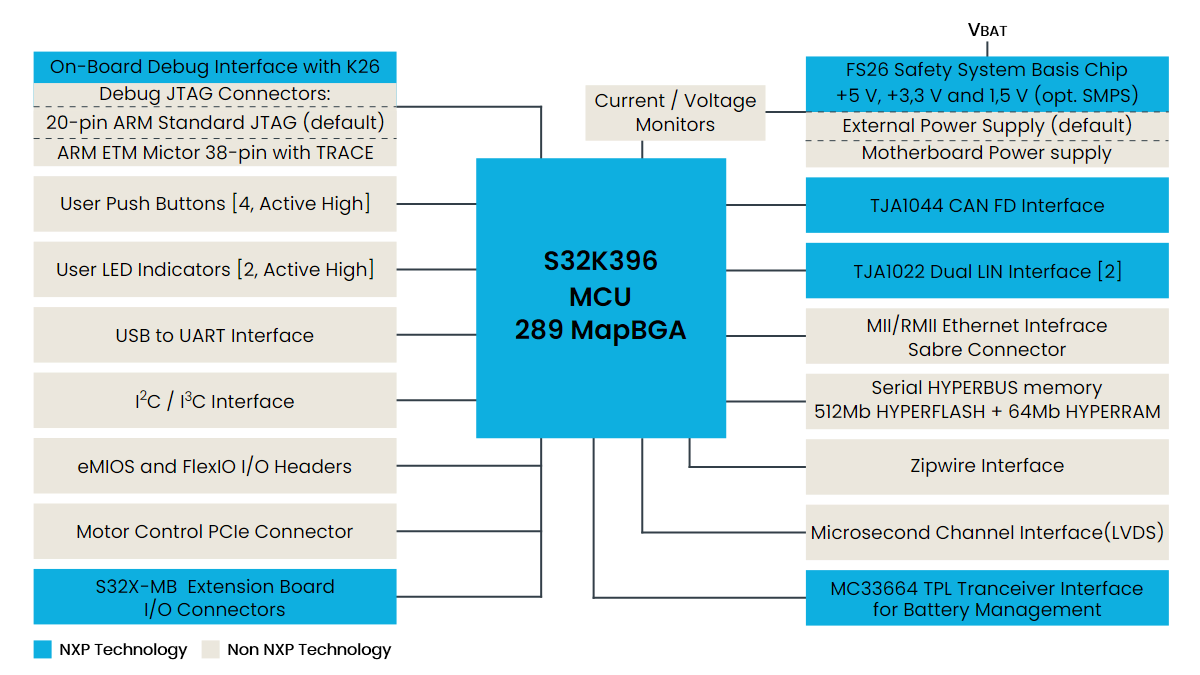 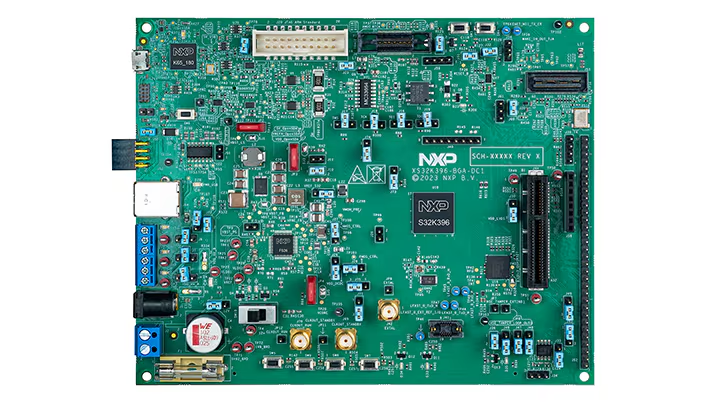                            

open_system('S32K39_CodeGen');

The opened model, includes the** FaultLogic** subsystem that has been implemented on previous exercises, along with other necessary instructions. The model already has been configured for hardware enablement. You need to add to the Simulink canvas multiple **NXP`s Model-Based Design Toolbox **blocks that has to be connected to their corresponding subsystems or other Simulink blocks, according to the instructions in the model.

### Requirements for the next exercises:

- Use **FreeMASTER** tool to visualize data in real-time;

- Use **ADC** component to emulate the input for our Fault monitoring algorithm;

- Use **DIO** component for clearing the existing faults using **SWITCH SW7** and to light the **BLUE D33** and **BLUE D34** LEDs on the **S32K396-BGA-DC1 EVB** if no faults are present;

- Use **PWM **component to glow the **BLUE D34 LED** on the **S32K396-BGA-DC1 EVB** if any fault has occurred;

## FreeMASTER tool for real-time data visualization

For the remaining Hands On session, we will test the algorithm functionality, using the NXP's **FreeMASTER** tool to visualize **AdcReadData, CurrentVoltage **and** PushButtons** variables in real-time. But first, we will configure the FreeMASTER communication.

To use the **FreeMASTER** tool, a** FreeMASTER configuration block** needs to be used for generating all the initialization and configuration code.

- Go to **SIMULATION** tab and click on **Library Browser**.

- Drag & Drop the **FreeMASTER Config** block from **S32K3xx Core, System, Peripherals and Utilities/Utility Blocks **Library into our Simulink model, indicated by the red area.

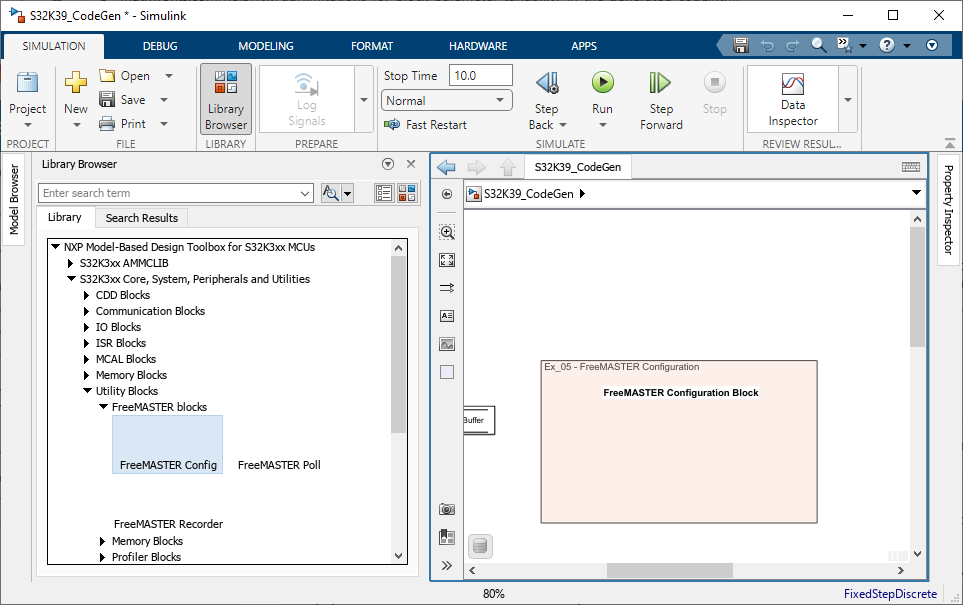

You can double click on this block to open the block mask and to change the settings for** Communication** that is used by the FreeMASTER driver, like connection type, UART instance, baudrate and internal interrupt priority.

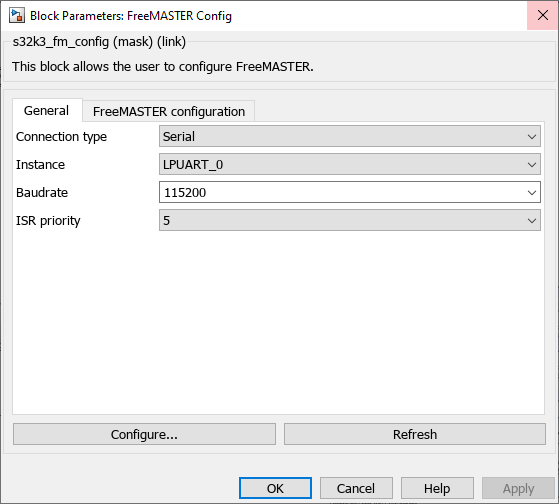

Simulink signals logged for **FreeMASTER** are already configured and can be visualized in the FreeMASTER project **S32K39_CodeGen.pmpx** located next to the model:

- AdcReadData

- ShuntCurrent

In the next exercise, we will deploy our first model on the target and check the data acquisition in FreeMASTER.

## Build & Deploy the Simulink Model to the Hardware

At this point, we can deploy our model on the hardware to establish the FreeMASTER communication between the host PC and board.

For this exercise:

- Click on the **HARDWARE** tab.

- Click on **Build, Deploy & Start** button.

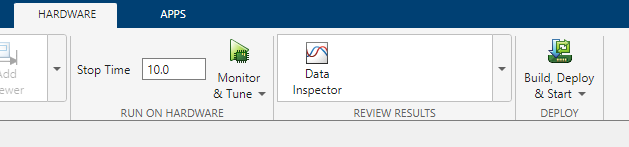

After a few seconds, the entire build process is completed and the application is flashed on the MCU Flash memory via the on board OpenSDA JTAG probe U34. 

## Check the application execution, using FreeMASTER

Alongside to the Simulink model, a **FreeMASTER** project already configured, the **S32K39_CodeGen.pmpx** file, .

Open the FreeMASTER project Outside MATLAB using the command below.

winopen('S32K39_CodeGen.pmpx')

### FreeMASTER Configuration

Before connecting to the hardware target, some additional configuration steps need to be performed:

- Go to **Project** tab and click on **Options...**

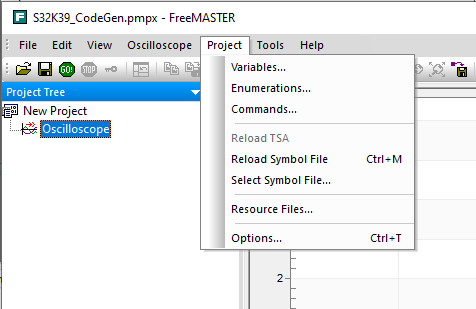

- The **Options** window will pop-up. Select the** COM port** assigned for the EVB and set the** Speed to 115200** as the Baudrate value configured in the Simulink model. This value needs to match the Baudrate from the **FreeMASTER Config** block in our Simulink model.

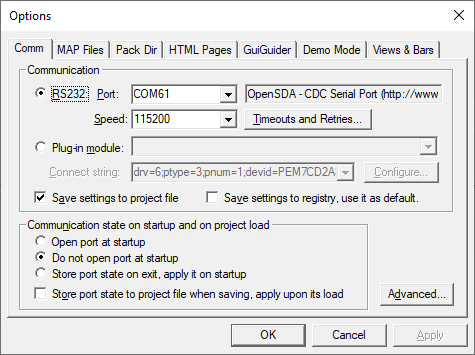

- Go to** MAP Files** tab and make sure that **S32K39_CodeGen.elf** executable file is selected in **Default symbol file**. This is required so the FreeMASTER find the variables defined in the elf file.

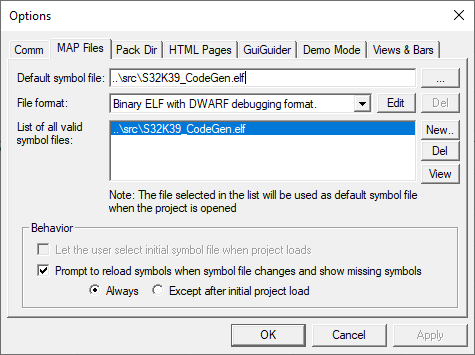

### Connect to FreeMASTER

To connect the **FreeMASTER** to the target hardware, click the green** GO** button:

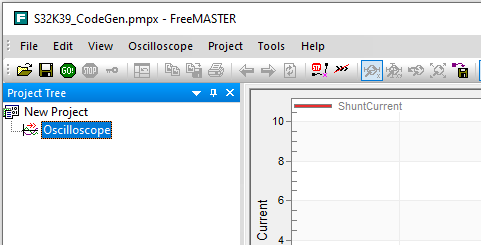

You should now see the variables values changing in real-time.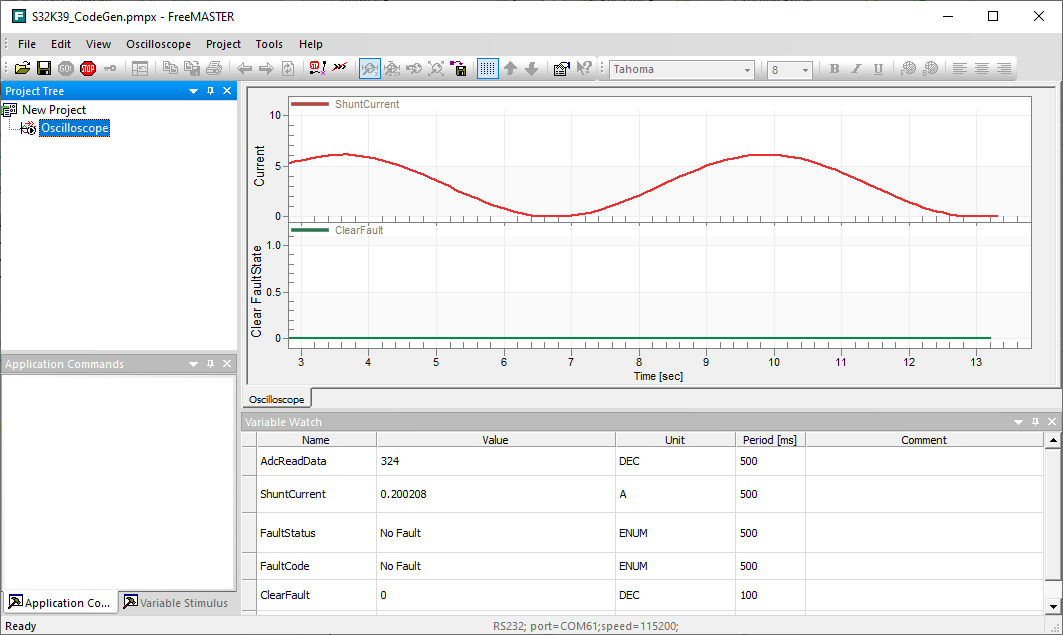

A **Sine Wave** block is currently delivering the **AdcReadData** signal. In the next exercise, the Sine Wave generation block will be replaced by the **ADC block** which will read data from an external potentiometer.

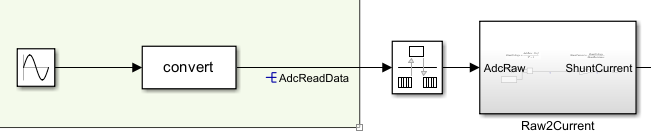

Go to the next exercise:

edit('Ex_06');